% ASEN-5044
% HWK 6 Q1

dt = 0.2;
A = [0,1;-100,-10];
B = [0;0];
Gamma = [0;1];
C = [1,0];
D = [0];
W = 10;
% generate DT model
Atilde = [A,B;C,D];
FG = expm( Atilde * dt);
g = Gamma * W * Gamma';
Z = dt * [-A, g;zeros(2,2), A'];
FGnoisy = expm(Z)

FGnoisy =    -1.9855   -0.3098   -0.0107   -0.1339
   30.9808    1.1126    0.1339    0.6907
         0         0    0.1506   -4.1928
         0         0    0.0419   -0.2687


Ftr = FGnoisy(3:4,3:4)

Ftr =     0.1506   -4.1928
    0.0419   -0.2687


FinvQ = FGnoisy(1:2,3:4)

FinvQ =    -0.0107   -0.1339
    0.1339    0.6907



Q = (Ftr)'* FinvQ

Q =     0.0040    0.0088
    0.0088    0.3760





% Q2

H = [1;1];
R2 = [1,0;0,4];
P1 = inv(H'*inv(R2)*H)

P1 = 0.8000

P2 = inv(inv(P1) + H'*inv(R2)*H)

P2 = 0.4000

K2 = P1*H'*inv(H*P1*H'+R2)

K2 =     0.4000    0.1000


P2check = P1 - K2*H*P1

P2check = 0.4000

% non weighted least squaresp
p1_ls=inv(H'*1*H)

p1_ls = 0.5000

p2_ls = inv(inv(p1_ls) + H'*(0.25)*H)

p2_ls = 0.4000

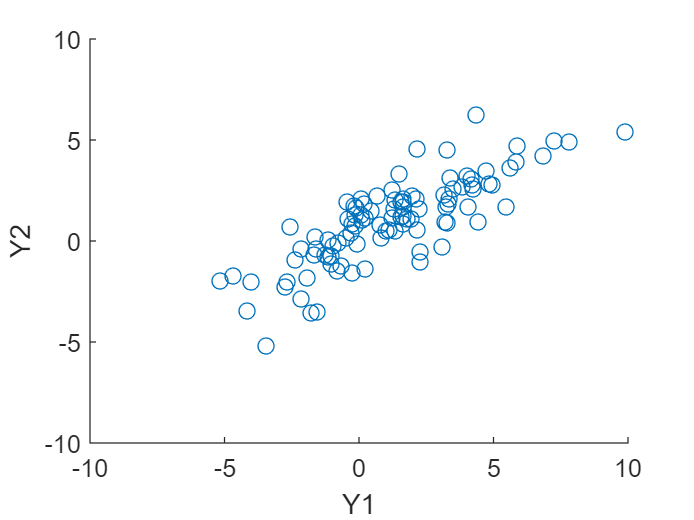



% Q3
% part A

rng(s);
N = 100;
nlist = (1:1:N);
R = [8, 5.15, 6.5; 5.15, 5 ,-4.07; 6.5, -4.07, 50];
x0 = 1; n0 = 1; z0 = 1;

X = [x0;n0;z0];
T = 100; 
H = eye(3);
% get matrix sqrt of R
Sv = chol(R,'lower');
Svs = repmat(Sv,N,1);
Hs = repmat(H,N,1);
Qk = randn(3,100);
yx = Hs* X + Svs*Qk;
y = yx(1:3,:);          

s1 = scatter(y(1,:), y(2,:));
xlim([-10,10]); ylim([-10,10]);
xlabel('Y1');ylabel('Y2');

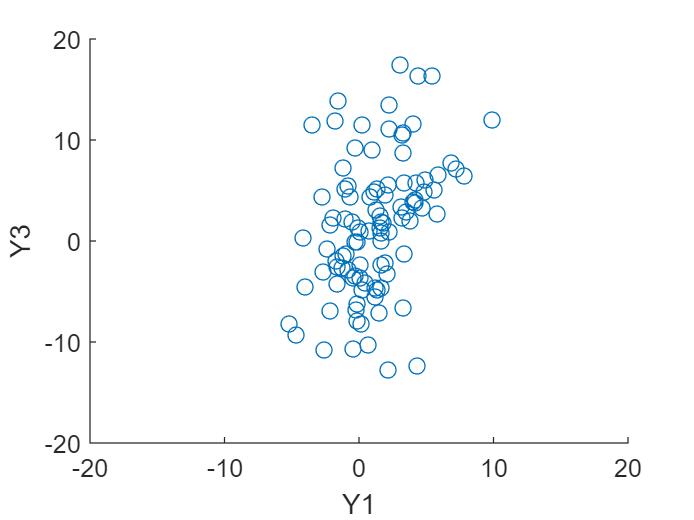

s2 = scatter(y(1,:), y(3,:));
xlim([-20,20]); ylim([-20,20]);
xlabel('Y1');ylabel('Y3');

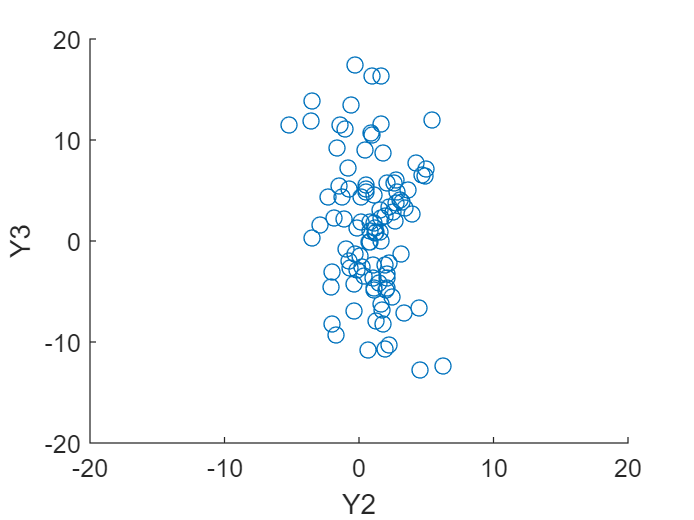

s3 = scatter(y(2,:),y(3,:));
xlim([-20,20]); ylim([-20,20]);
xlabel('Y2');ylabel('Y3');

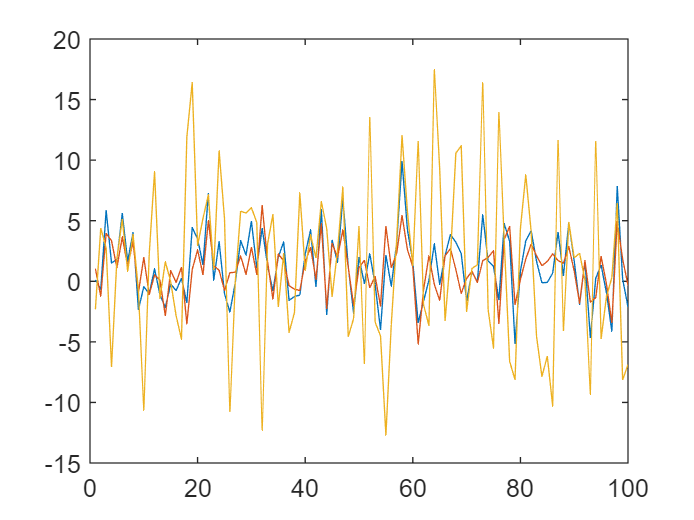


% Part B
Yetamean = sum(y(1,:))/N;
Ynumean = sum(y(2,:))/N;
Yzemean = sum(y(3,:))/N;

cov_y = cov(y');

% Part C
for k = 1:3
    xls3(:,k) = inv(H'*inv(R)*H) * H'* inv(R) * y(:,k);
end
% calculate error covariance
for k = 1:10
    xls10(:,k) = inv(H'*inv(R)*H) * H'* inv(R) * y(:,k);
end

for k = 1:100
    xls100(:,k) = inv(H'*inv(R)*H) * H'* inv(R) * y(:,k);
end

plot(nlist,xls100)


% Part D
ymsmt = importdata()